# **Abschluss Projekt: Mars**

clear all

**Laden von Konstanten**

Zu Beginn des Codes werden wichtige Konstanten wie der Erdradius, die Erdmasse, die Sonnenmasse und andere relevante Werte aus einer externen Datei (`data/constants.mat`) geladen. Diese Konstanten sind entscheidend für die Berechnungen der Trajektorie der Sonde und umfassen beispielsweise die Anfangsgeschwindigkeit der Sonde und den Abstand der Erde von der Sonne.

load('data/constants.mat');

**Model Sonnensystem**

Für die Berechnung der Trajotery der Sonde wird ein Modell des Sonnensystems benötigt. *modelSolarSystem.m* erstellt eine Animation des Sonnensystems *positionsCalcPlanets.m *dagegen, nimmt eine Zeitpunkt und gibt die Position von Erde und Mars zurück.

Die Umlaufbahnen werden aus den in *constants.mat* gespreicherten Umlaufzeiten von Erde und Mars sowie deren Bahnradien (vereinfacht zu einem Kreis) wie folgt berechnet:

$\omega = \frac{2\pi}{T}$ mit $T = Umlaufzeit$


$$\theta = \omega * t$$


$x = r * sin(\theta)$ mit $r=Bahnradius$

$y=r * cos(\theta)$ mit $r=Bahnradius$

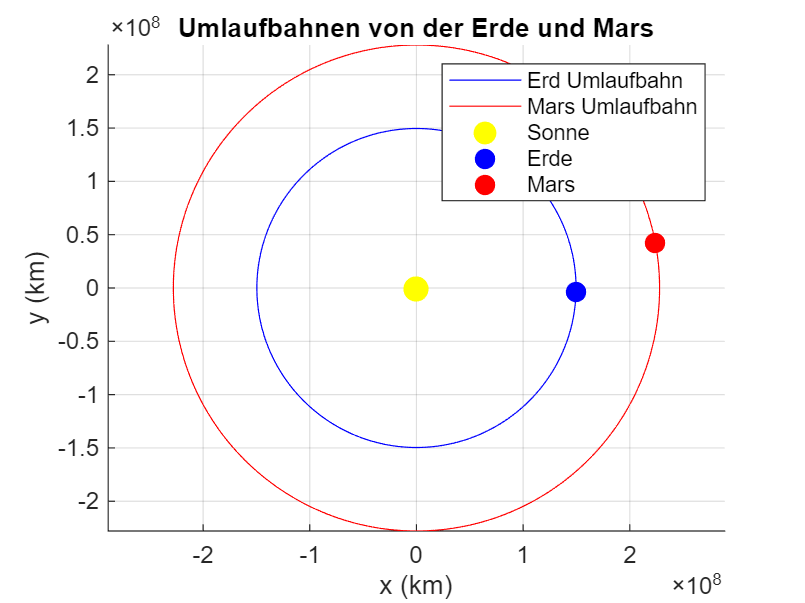

modelSolarSystem(constants);

**Umrechnung der Simulationszeit**

Die vorgegebene Simulationszeit ist in Tagen angegeben. Diese wird in Sekunden umgerechnet, da die ODE-Lösung (Ordinary Differential Equations) in der Regel eine Zeiteinheit in Sekunden benötigt. Die Umrechnung erfolgt durch Multiplizieren mit der Anzahl der Stunden pro Tag (24) und der Anzahl der Sekunden pro Stunde (3600).

tSpan = [0, constants.simulationTime *24 * 3600];

**Festlegung der Anfangsbedingungen**

Die Anfangsbedingungen für die Simulation der Sonde werden definiert. Die Position der Sonde wird zu Beginn auf der Erdumlaufbahn gesetzt, wobei der Abstand von der Erde zur Sonne durch die Summe des Erdradius und des Abstands der Erde von der Sonne bestimmt wird. Die Anfangsgeschwindigkeit der Sonde setzt sich aus der Geschwindigkeit der Erde und der zusätzlichen Geschwindigkeit, die für die Mission erforderlich ist, zusammen.

pos0 = [constants.earthOrbitRadius + constants.earthRadius, 0, 0, constants.probeIntialVelocity + constants.earthVelocity];

**Defenieren der Differentialgleichung**

Um die Flugbahn der Sonde zu berechnen, wird eine Differentialgleichung benötigt.


$$\frac{dr}{dt} = v$$



$$\frac{dv}{dt} = a = - \frac{GM_{\text{sonne}}}{|\vec{r}|^3}\vec{r}$$


Defeniert wird die differntial Gleichung in dem Vektor $u$:


$$\vec{u} = \pmatrix{  x \cr y \cr v_x \cr v_y }$$


dabei sind $x$ und $y$ der Positions Vektor $\vec{r}$

und $v_x$ und $v_y$ der Geschwindigkeits Vektor $\vec{v}$

daraus ergibt sich:


$$\frac{d}{dt} \pmatrix{x \cr y \cr v_x \cr v_y} = \pmatrix{v_x \cr v_y \cr -\frac{GM_\text{Sonne}}{r^3} x \cr -\frac{GM_\text{Sonne}}{r^3} y}$$


**Lösen der Differential Gleichung**

Mit Hilfe des bereits bekannten numerischen solvers für normale Differential Gleichungen ode45 kann man die Differentialgleichung lösen um die Flugbahn zu erhalten.

[t, u] = ode45(@(t, pos) calculateTrajectory(constants, pos), tSpan, pos0);

**Visualisieren der Flugbahn**

Mit einer simplen Plot Routine, kann man die FLugbahn der Sonne Visualisieren, dabei fällt auf, das es Auflösungs Probleme, beim Lösen der Differential Gleichung gab.

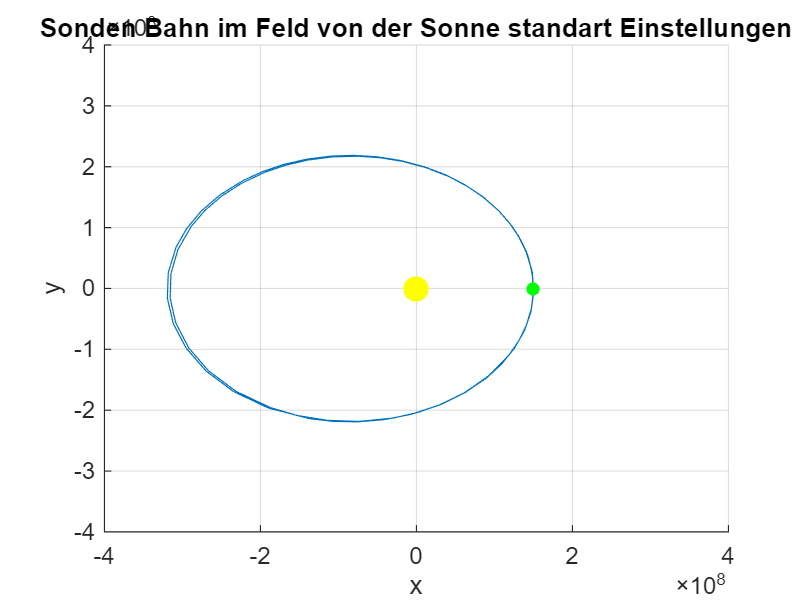

plotLimit = [-4e8, 4e8];

figure;
hold on;
plot(u(:,1), u(:,2));
plot(0,0, 'yo','MarkerSize',10,'MarkerFaceColor','y')
plot(pos0(1),pos0(2), 'go', 'MarkerSize',5,'MarkerFaceColor','g');
grid on;
title('Sonden Bahn im Feld von der Sonne standart Einstellungen');
xlabel('x');
ylabel('y');
xlim(plotLimit);
ylim(plotLimit);
hold off;

**Anpassung der ode45 Parameter**

Wie in unsere Übung, kann man die Parameter $RelTol$ für die Relative Toleranz und $AbsTol$ für die Absoulte Toleranz anpassen, um die Fehler beim Lösen der Differntial gleichung zu minimieren.

options = odeset('RelTol', 1e-13, 'AbsTol', 1e-16 * ones(size(pos0)));

**Erneutes Lösen und Visualiseren**

Lösen wir die Differntial Gleichung nun mit den neuen Einstellungen und Plotten diese wieder, kann man erkennen, das die Ungenauigkeiten verschwunden sind.

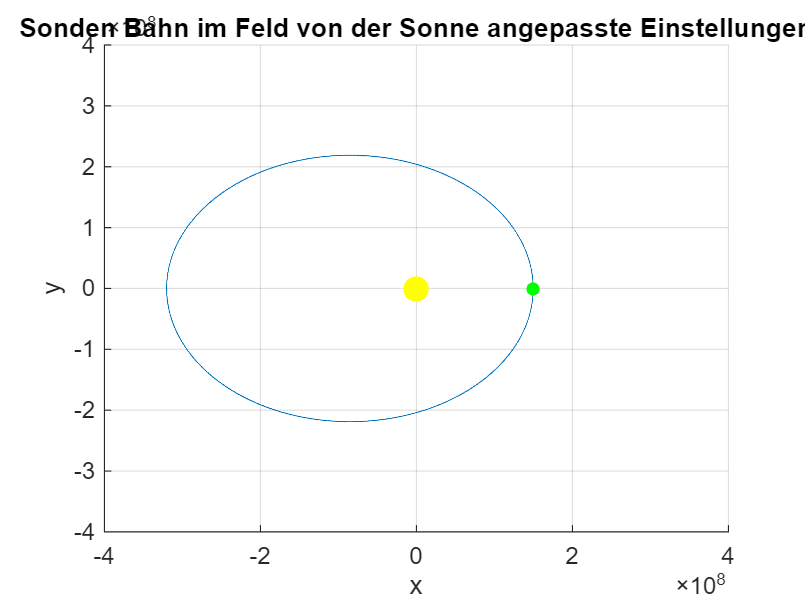

[t, u] = ode45(@(t, pos) calculateTrajectory(constants, pos), tSpan, pos0, options);

figure;
hold on;
plot(u(:,1), u(:,2));
plot(0,0, 'yo','MarkerSize',10,'MarkerFaceColor','y')
plot(pos0(1),pos0(2), 'go', 'MarkerSize',5,'MarkerFaceColor','g');
grid on;
title('Sonden Bahn im Feld von der Sonne angepasste Einstellungen');
xlabel('x');
ylabel('y');
xlim(plotLimit);
ylim(plotLimit);
hold off;


v_mars = fminsearch(@(v0)Trajektorie1(v0,constants),8.8)

v_mars = 9.1575

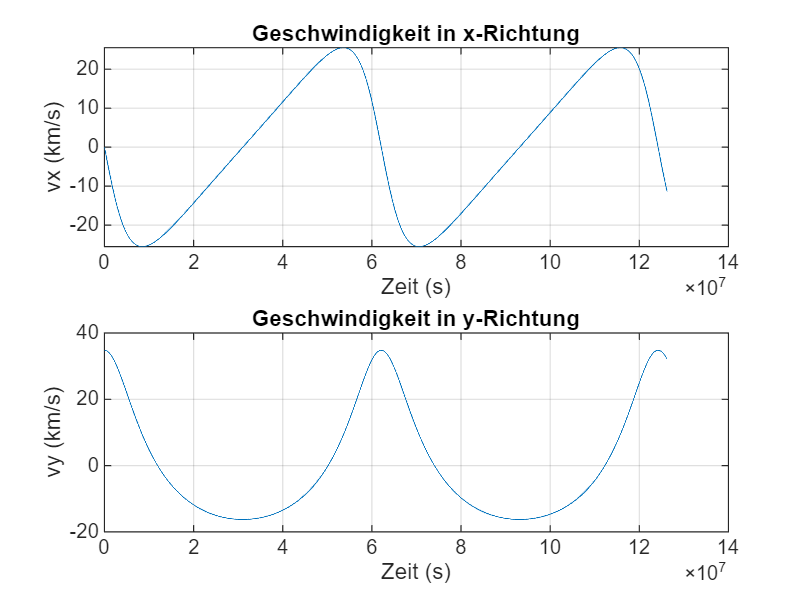


%% figure; visualisation der Geschwindigkeit (nur für Info)
figure;
subplot(2,1,1);
plot(t, u(:,3)); % vx (Geschwindigkeit in x)
xlabel('Zeit (s)');
ylabel('vx (km/s)');
title('Geschwindigkeit in x-Richtung');
grid on;

subplot(2,1,2);
plot(t, u(:,4)); % vy (Geschwindigkeit in y)
xlabel('Zeit (s)');
ylabel('vy (km/s)');
title('Geschwindigkeit in y-Richtung');
grid on;

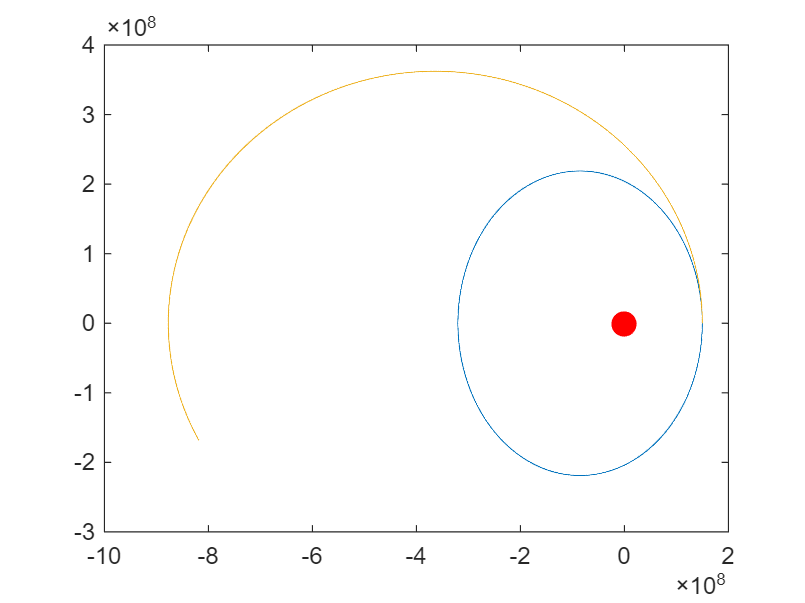





figure;

plot(u(:,1), u(:,2))
hold on;
plot(0,0, 'ro','MarkerSize',10,'MarkerFaceColor','r')

pos0 = [constants.earthOrbitRadius + constants.earthRadius, 0, 0, v_mars + constants.earthVelocity];
[t, u] = ode45(@(t, pos) calculateTrajectory(constants, pos), tSpan, pos0, options);

plot(u(:,1), u(:,2))
hold on;